Author: **Arjan Gupta**

Due: March 27, 2023

Class: RBE 501

Institution: Worcester Polytechnic Institute

# Forward Dyanamics of Three Link Manipuator

clear; clc; close all;

## Build Robot

### Create Rigid Body Elements

First, let us create a `rigidBodyTree` robot model. Then, we create the 3 rectangular arms of the robot.

robot = rigidBodyTree("DataFormat","column");
base = robot.Base;
arm1 = rigidBody("arm1");
arm2 = rigidBody("arm2");
arm3 = rigidBody("arm3");

Next, we create collision objects using the given link lengths in the prompt of this assignment. We use `Pose` in order to shift the frame origin down along the x-axis. The default origin is in the center of the object. 

% Link lengths
L1 = 4.0;
L2 = 3.0;
L3 = 2.0;
% Create collision objects for each body
coll1 = collisionBox(L1,0.2,0.2); % box: length, width, height (x,y,z)
coll1.Pose = trvec2tform([L1/2 0 0]);
coll2 = collisionBox(L2,0.2,0.2); % box: length, width, height (x,y,z)
coll2.Pose = trvec2tform([L2/2 0 0]);
coll3 = collisionBox(L3,0.2,0.2); % box: length, width, height (x,y,z)
coll3.Pose = trvec2tform([L3/2 0 0]);
% Add the collision bodies to the rigid body objects.
addCollision(arm1,coll1)
addCollision(arm2,coll2)
addCollision(arm3,coll3)

### Attach Joints

We specify the joints as revolute and set them to rotate around the z-axis.

jnt1 = rigidBodyJoint("jnt1","revolute");
jnt2 = rigidBodyJoint("jnt2","revolute");
jnt3 = rigidBodyJoint("jnt3","revolute");
jnt1.JointAxis = [0 0 1];
jnt2.JointAxis = [0 0 1];
jnt3.JointAxis = [0 0 1];

In the prompt of this assignment, we are given the following DH table.


$$\matrix{
\text{Link}    	& a_i 	& \alpha_i &  d_i & \theta_i  \cr
1			& 0 			& 0	& 0	& \theta_1			\cr
2			& L_1 		& 0		& 0	& \theta_2		\cr
3			& L_2 			& 0			& 0 & \theta_3	\cr
}$$


% Joint variables
theta1 = 0;
theta2 = 0;
theta3 = 0;
% DH table
dhparams = [0 0  0 theta1;
            L1 0 0 theta2;
            L2 0 0 theta3];
setFixedTransform(jnt1,dhparams(1,:),'dh');
setFixedTransform(jnt2,dhparams(2,:),'dh');
setFixedTransform(jnt3,dhparams(3,:),'dh');

### Set Physical Properties

% Masses (in kgs), given in assignment prompt
m1 = 20;
m2 = 15;
m3 = 10;
% Moments of inertia (in kgm^2), given in assignment prompt
I1 = 0.5;
I2 = 0.2;
I3 = 0.1;
% Set the masses
arm1.Mass = m1;
arm2.Mass = m2;
arm3.Mass = m3;
% Set the centers of masses
arm1.CenterOfMass = [L1/2, 0, 0];
arm2.CenterOfMass = [L2/2, 0, 0];
arm3.CenterOfMass = [L3/2, 0, 0];
% Set the inertias
arm1.Inertia = [I1,I1,I1,0,0,0];
arm2.Inertia = [I2,I2,I2,0,0,0];
arm3.Inertia = [I3,I3,I3,0,0,0];

### Assemble Robot

To assemble the robot, we add each joint to the body, and then add the body to the tree.

bodies = {base,arm1,arm2,arm3};
joints = {[],jnt1,jnt2,jnt3};
for i = 2:length(bodies)
    bodies{i}.Joint = joints{i};
    addBody(robot,bodies{i},bodies{i-1}.Name)
end

## Problem 1

In this problem we implement the forward dynamics and plot the joint accelerations and velocities in response to actuator torques.

% Set gravity direction
robot.Gravity = [0; -9.81; 0];
% Set joint torques and velocities, as given in assignment prompt
jointTorqs = [20;5;1];
jointVelsInit = [0;0;0];
% Set initial position, as given in assignment prompt
initialPosition = [-pi/3;pi/2;pi/6];

We want to calculate the forward dynamics over a time period. Let us choose a time period of 10 seconds with 10 ms step.

First, we define a time array and time increment (step) size.

time_step = 0.043; % arbitrarily small time step
time_arr = 0:time_step:5;
[~,time_arr_len] = size(time_arr);

Now we can run a loop of calculations for the forward dynamics over this time.

% Declare 3D arrays to capture lists of acceleration, velocity, and
% position vectors
jointAccels = zeros(3,1,time_arr_len);
jointVels = zeros(3,1,time_arr_len+1);
jointVels(:,:,1) = jointVelsInit;
jointAngles = zeros(3,1,time_arr_len+1);
jointAngles(:,:,1) = initialPosition;
i = 1;
% Run the loop for forward dynamics
for t = time_arr
    jointAccels(:,:,i) = forwardDynamics(robot,jointAngles(:,:,i),jointVels(:,:,i),jointTorqs);
    jointVels(:,:,i+1) = jointAccels(:,:,i)*time_step;
    jointAngles(:,:,i+1) = jointAccels(:,:,i)*time_step*time_step;
    i = i + 1;
end
disp(jointAccels)


(:,:,1) =

 -362.4000
  360.5062
    2.3415


(:,:,2) =

 -585.1054
  583.2001
    1.3286


(:,:,3) =

 -338.6105
  336.7052
    1.3286


(:,:,4) =

 -605.9426
  604.0373
    1.3286


(:,:,5) =

 -311.6496
  309.7443
    1.3286


(:,:,6) =

 -628.0684
  626.1631
    1.3286


(:,:,7) =

 -282.4672
  280.5619
    1.3286


(:,:,8) =

 -650.1729
  648.2676
    1.3286


(:,:,9) =

 -252.7906
  250.8853
    1.3286


(:,:,10) =

 -670.6210
  668.7157
    1.3286


(:,:,11) =

 -224.9162
  223.0109
    1.3286


(:,:,12) =

 -687.9077
  686.0024
    1.3286


(:,:,13) =

 -201.0656
  199.1604
    1.3286


(:,:,14) =

 -701.1869
  699.2816
    1.3286


(:,:,15) =

 -182.5825
  180.6773
    1.3286


(:,:,16) =

 -710.5011
  708.5958
    1.3286


(:,:,17) =

 -169.5412
  167.6359
    1.3286


(:,:,18) =

 -716.5533
  714.6480
    1.3286


(:,:,19) =

 -161.0352
  159.1299
    1.3286


(:,:,20) =

 -720.2671
  718.3618
    1.3286


(:,:,21) =

 -155.8038
  153.8985
    1.3286


(:,:,22) =

 -722.459

disp(jointVels)


(:,:,1) =

     0
     0
     0


(:,:,2) =

  -15.5832
   15.5018
    0.1007


(:,:,3) =

  -25.1595
   25.0776
    0.0571


(:,:,4) =

  -14.5603
   14.4783
    0.0571


(:,:,5) =

  -26.0555
   25.9736
    0.0571


(:,:,6) =

  -13.4009
   13.3190
    0.0571


(:,:,7) =

  -27.0069
   26.9250
    0.0571


(:,:,8) =

  -12.1461
   12.0642
    0.0571


(:,:,9) =

  -27.9574
   27.8755
    0.0571


(:,:,10) =

  -10.8700
   10.7881
    0.0571


(:,:,11) =

  -28.8367
   28.7548
    0.0571


(:,:,12) =

   -9.6714
    9.5895
    0.0571


(:,:,13) =

  -29.5800
   29.4981
    0.0571


(:,:,14) =

   -8.6458
    8.5639
    0.0571


(:,:,15) =

  -30.1510
   30.0691
    0.0571


(:,:,16) =

   -7.8510
    7.7691
    0.0571


(:,:,17) =

  -30.5515
   30.4696
    0.0571


(:,:,18) =

   -7.2903
    7.2083
    0.0571


(:,:,19) =

  -30.8118
   30.7299
    0.0571


(:,:,20) =

   -6.9245
    6.8426
    0.0571


(:,:,21) =

  -30.9715
   30.8896
    0.0571


(:,:,22) =

   -6.6996
    6.6176

In order to plot the data, we flatten the arrays for acceleration and velocities into their own 2D arrays.

% Acceleration 2D arrays
accel_joint1 = reshape(jointAccels(1,1,:),[1,time_arr_len]);
accel_joint2 = reshape(jointAccels(2,1,:),[1,time_arr_len]);
accel_joint3 = reshape(jointAccels(3,1,:),[1,time_arr_len]);

% Velocity 2D arrays
vel_joint1 = reshape(jointVels(1,1,:),[1,time_arr_len+1]);
vel_joint2 = reshape(jointVels(2,1,:),[1,time_arr_len+1]);
vel_joint3 = reshape(jointVels(3,1,:),[1,time_arr_len+1]);

Now we come up with the acceleration and velocity evolution plots.

### Plot acceleration values against time

Let us now view our joint accelerations against time.

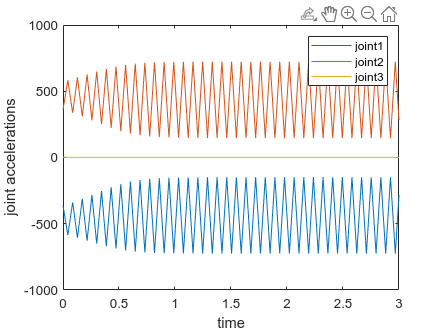

plot(time_arr, accel_joint1)
hold on
plot(time_arr, accel_joint2)
hold on
plot(time_arr, accel_joint3)
xlabel("time")
ylabel("joint accelerations")
xlim([0,3])
ylim([-1000,1000])
legend('joint1','joint2','joint3')
hold off

### Plot velocity values against time

Let us also plot the joint velcoities versus time.

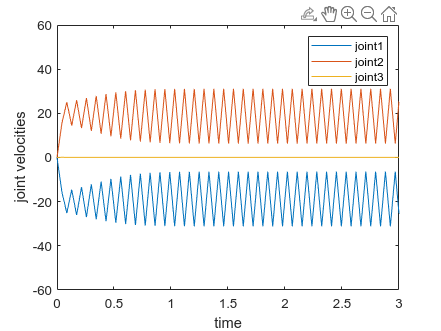

plot([time_arr 10.1], vel_joint1)
hold on
plot([time_arr 10.1], vel_joint2)
hold on
plot([time_arr 10.1], vel_joint3)
xlabel("time")
ylabel("joint velocities")
xlim([0,3])
ylim([-60,60])
legend('joint1','joint2','joint3')
hold off

## Problem 2